## Цель работы:

Освоение управления линейными объектами с помощь метода внутренней модели на базе уравнений Франкиса-Дэвисона (комбинированный регулятор, регулятор с прямыми связями).

## Исходные данные:

syms t
A = [2 6; 1 0];
B = [4; 1];
C =[2 0];
D = 6; 
B_f = [1; 3];
lambda_1 = -10;
lambda_2 = -9;
w_g = 4;
w_f = 5;
g(t) = 2*sin(w_g*t + 2);
f(t) = 8*cos(w_f*t + 2);

g(t) = 5*sin(w_g*t + 1);
f(t) = 8*cos(w_f*t + 2);


t_pn = 0.3;
sigma_n = 5;
A = [5 3
    -2 0];
B = [0
    3];
C = [5 0];
B_f = [4
    1];
lambda_1 = -16;
lambda_2 = -8;
w_g = 2;
w_f = 1;
g(t) = 2*sin(w_g*t);
f(t) = 6*sin(w_f*t+2);


## Ход работы

### 1. Задача слежения. 

Целью управления является обеспечение выполнения следующего целевого равенства

#### 1.1 Проверка объекта управления на свойство полной управляемости.

N = ctrb(A, B);
switch rank(N)
    case rank(A)
        disp('система полностью управляема')
    otherwise
        disp('система не управляема')
end

система полностью управляема


#### 1.2 Формирование модели задающего воздействия на основе метода последовательного дифференцирования в виде:

xi_1(t) = g(t)

$$xi\_1(t) = 2\,\sin\left(2\,t\right)$$

xi_2(t) = diff(xi_1(t))

$$xi\_2(t) = 4\,\cos\left(2\,t\right)$$

k_xi_2_dot = double(diff(xi_2(t))/xi_1(t))

k_xi_2_dot = -4

xi_2_dot(t) = k_xi_2_dot * xi_1(t);
xi_0 = double([xi_1(0); xi_2(0)])

xi_0 =      0
     4


Gamma_g = [0 1
    -w_g^2 0];
H_g = [1 0];

#### **1.3 Конструирование эталонной модели по желаемым корням:**


$${\left\{\begin{array}{c}
MГ-AM=BH\\
K=-H*M^{-1} 
\end{array}$$


Gamma = [lambda_1 0
    0 lambda_2];
H = [1 1];
M = sylv(-A, Gamma, B*H)

M =     0.0263    0.0818
   -0.1842   -0.3545


K = -H/M

K =    29.6667    9.6667


#### 1.4. Вычисление матрицы и матрицы прямых связей на основе уравнения типа Франкиса-Дэвисона:


$${\left\{\begin{array}{c}
BL_g =M_g Г_g -\left(A{\left.-B*K\right)M}_g \right.\\
H_g =\left(C-D*K\right)M_g +DL_g 
\end{array}\right)}$$


Mg = sym('mg', [2 2]);
Lg = sym('lg', [1 2]);
eqn1 = B*Lg == Mg*Gamma_g - (A - B*K)*Mg;
eqn2 = H_g == (C-D*K)*Mg + D*Lg;
s = solve([eqn1; eqn2],[Mg; Lg]);
Lg = double([s.lg1 s.lg2])

Lg =     0.6115    0.7429


Mg = double([s.mg1_1 s.mg1_2
    s.mg2_1 s.mg2_2])

Mg =     0.0749    0.0394
   -0.1774   -0.0407


Модель слежения ошибки:


$${\left\{\begin{array}{c}
\dot{e} =Ae+BL_g \xi_g -Bu\\
\varepsilon =Ce+DL_g \xi_g -Du
\end{array}\$$


#### 1.6. Вычисление собственных чисел матрицы замкнутой системы и сравнение их с корнями требуемого характеристического полинома.

eig(A-B*K)

ans =    -8.0000
  -16.0000


#### 1.7 Определим матрицу $\bar{G}$, которая строится на основе требуемых показателей качества $t_{пн} \ ,\;\sigma_н \$  и матрицу входа модели , которая определяется из условия полной управляемости пары $\left(\bar{G} \right.$, $\left.\bar{L} \right)$:

Поскольку желаемое перерегулирование больше 4,5% используем полином Баттерворта:

w = 2.9/t_pn;
syms s
a(s) = s^2 + sqrt(2)*w*s + w^2;
a_s = sym2poly(a(s));
G_overline = [0 -a_s(3)
    1 -a_s(2)]

G_overline =          0  -93.4444
    1.0000  -13.6707


L_overline = [0
    1]

L_overline =      0
     1


rank(ctrb(G_overline, L_overline))

ans = 2

#### 1.8. При синтезе наблюдателя состояния сигнала задания решается матричное уравнение типа Сильвестра вида:

Mg_ov = sym('mg_ov', [2 2]);
eqn = Mg_ov*Gamma_g-G_overline*Mg_ov == L_overline*H_g;
sol = solve(eqn, Mg_ov);
Mg_ov = double([sol.mg_ov1_1 sol.mg_ov1_2
    sol.mg_ov2_1 sol.mg_ov2_2])

Mg_ov =    -0.9554    0.1460
    0.0063    0.0102


#### 1.9. Вычисление корней характеристического полинома матрицы и сравнение их с корнями требуемого характеристического полинома.

[eig(G_overline) double(solve(a==0))]

ans =   -6.8354 + 6.8354i  -6.8354 - 6.8354i
  -6.8354 - 6.8354i  -6.8354 + 6.8354i


#### 1.10. Моделирование системы слежения

Схема моделирования:

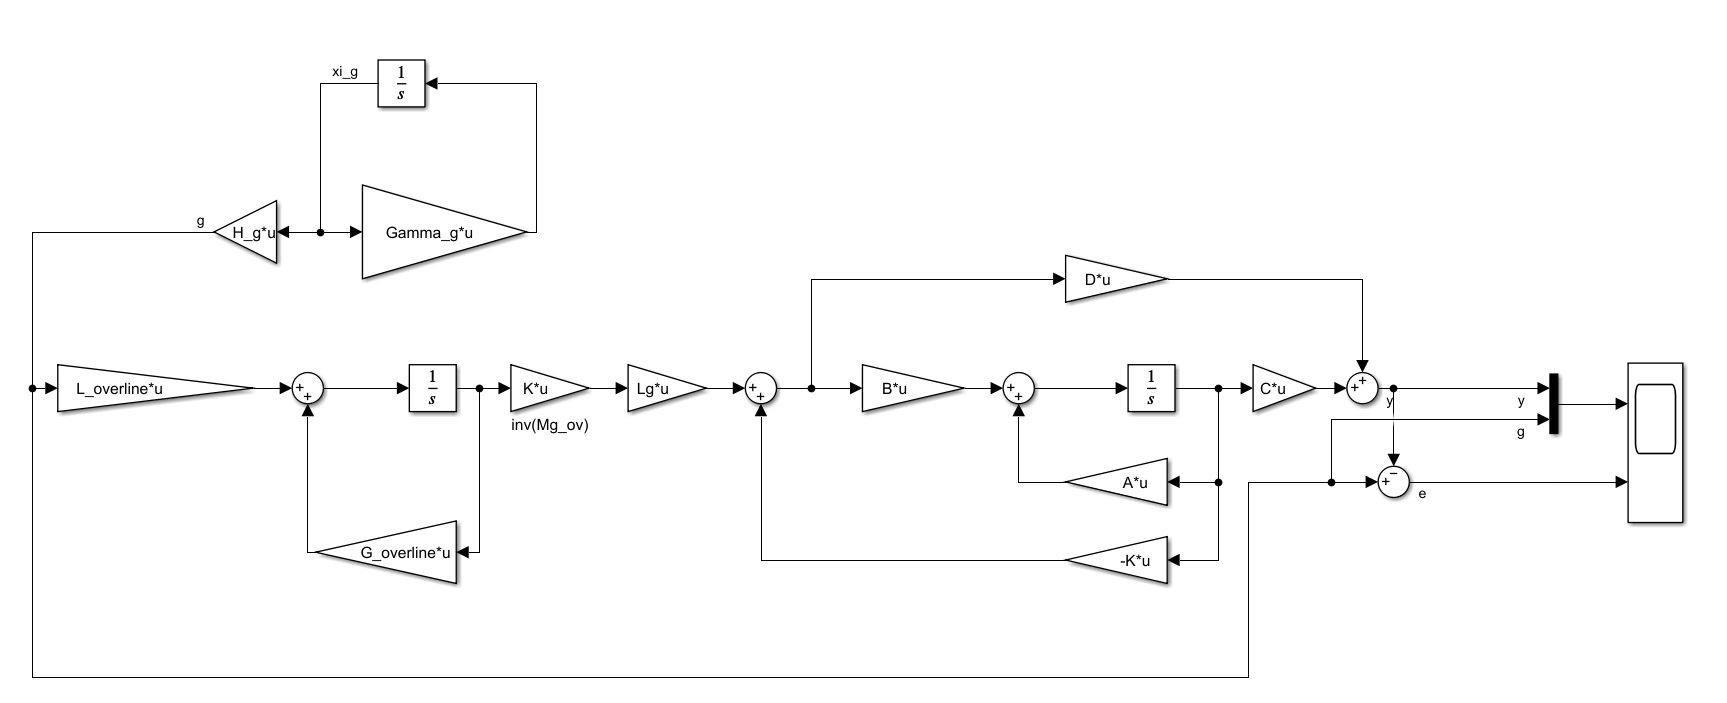

Результат моделирования:

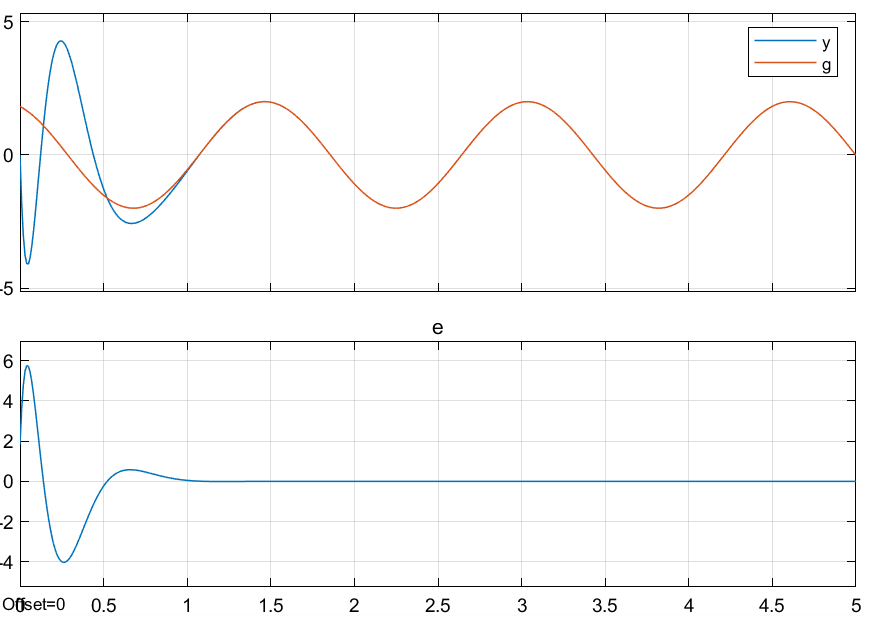

### **2. Задача компенсации возмущений по входу (стабилизация в условиях внешних возмущений).**

Целью управления является обеспечение выполнения следующего целевого равенства:


$$\lim_{t\to \infty } \left|\left|y\left(t\right)\right|\right|=0$$


#### 2.1. Проверка объекта управления на свойства полной управляемости и наблюдаемости

rank(ctrb(A,B))

ans = 2

пара A,B полностью управляема

rank([C; C*A])

ans = 2

пара A,C полностью наблюдаема

#### 2.2. Формирование модели возмущающего воздействия на основе метода последовательного дифференцирования в виде:


$${\left\{\begin{array}{c}
{\dot{\xi} }_f =Г_f \xi_f \\
f=H_f \xi_f 
\end{array}\$$


xi_f_1(t) = f(t)

$$xi\_f\_1(t) = 6\,\sin\left(t+2\right)$$

xi_f_2(t) = diff(xi_f_1(t))

$$xi\_f\_2(t) = 6\,\cos\left(t+2\right)$$

k_xi_f_dot_2(t) = diff(xi_f_2(t))/xi_f_1(t)

$$k\_xi\_f\_dot\_2(t) = -1$$

xi_f_dot_2(t) = k_xi_f_dot_2(t) * xi_f_1(t)

$$xi\_f\_dot\_2(t) = -6\,\sin\left(t+2\right)$$

xif_0 = double([xi_f_1(0); xi_f_2(0)])

xif_0 =     5.4558
   -2.4969


Gamma_f = [0 1
    -w_f^2 0];
H_f = [1 0];

#### 2.3. Конструирование эталонной модели по желаемым корням .Нахождение матрицы M и матрицы линейных стационарных обратных связей K из уравнений:


$${\left\{\begin{array}{c}
MГ-AM=BH\\
K=-H*M^{-1} 
\end{array}$$


Gamma = [lambda_1 0
    0 lambda_2];
H = [1 1];
M = sylv(-A, Gamma, B*H)

M =     0.0263    0.0818
   -0.1842   -0.3545


K = -H/M

K =    29.6667    9.6667


#### 2.4. Расчёт матриц  и из совместного решения двух векторно-матричных уравнений Франкиса-Дэвисона:


$${\left\{\begin{array}{c}
BL_f +B_f H_f =M_f Г_f -\left(A-BK\right)M_f \\
\left(C-DK{\left.\right)M}_f +DL_f =0\right.
\end{array}$$


Mf = sym('mf', [2 2]);
Lf = sym('lf', [1 2]);
eqn1 = B*Lf +B_f*H_f == Mf*Gamma_f - (A - B*K)*Mf;
eqn2 = (C-D*K)*Mf + D*Lf == 0;
s = solve([eqn1; eqn2],[Mf; Lf]);
Lf = double([s.lf1 s.lf2])

Lf =   -12.8161    4.8736


Mf = double([s.mf1_1 s.mf1_2
    s.mf2_1 s.mf2_2])

Mf =     0.0966    0.3586
   -1.6138   -0.5655


#### 2.5. Моделирование системы компенсации.

Схема моделирования:

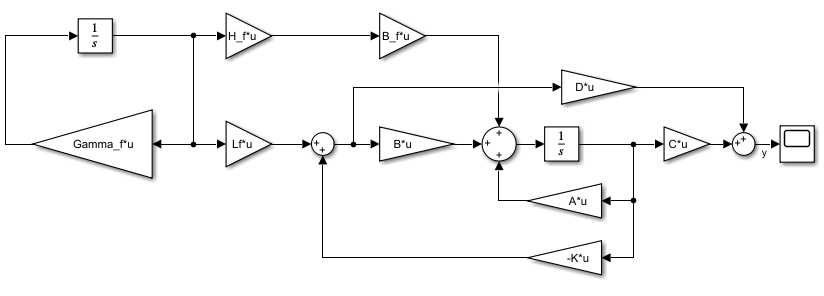

Результат моделирования:

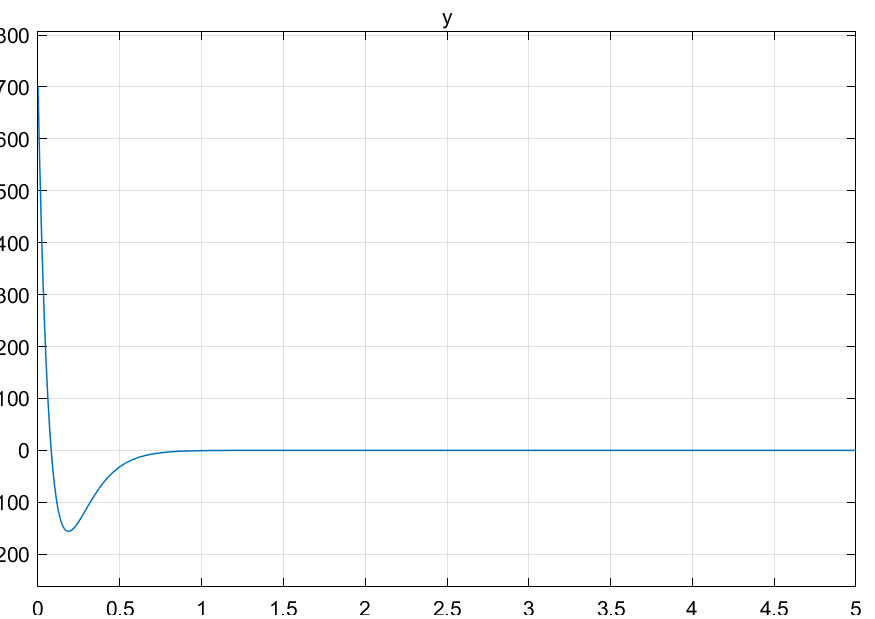

#### 2.6. По требуемым показателям качества $t_{\textrm{пн}} \;и\;\sigma_H$ назначаются коэффициенты требуемого характеристического полинома, предназначенных для синтеза наблюдателя

syms s
a(s) = s^4+2.613*w*s^3++3.414*w^2*s^2+2.613*w^3*s + w^4;
a_s = sym2poly(a(s));

#### 2.7. Для расширенного наблюдателя, описание которого определяется матрицей $\bar{F_н }$, назначаются матрицы эталонной модели $\bar{Г_н }$ и $\bar{Н_н }$, матрица $Г_н$ определяется на основе требуемых корней или коэффициентов требуемого характеристического полинома, матрица $\bar{Н_н }$ находится из условия полной наблюдаемости эталонной модели.

r = roots(a_s);
G_bar_H = [real(r(1)) imag(r(1)) 0 0
imag(r(2)) real(r(2)) 0 0
0 0 real(r(3)) imag(r(3))
0 0 imag(r(4)) real(r(4))] 

G_bar_H =    -3.6987    8.9311         0         0
   -8.9311   -3.6987         0         0
         0         0   -8.9308    3.6995
         0         0   -3.6995   -8.9308


H_bar_H = [1 1 1 1];

#### 2.8. Решение задачи синтеза расширенного наблюдателя состоит в решении матричного уравнения типа Сильвестра


$$\overset{-}{М_н } \ \overset{-}{Г_н } -\overset{-}{М_н } \ \overset{-}{А^т } =\overset{-}{Н_н } \ \overset{-}{А^т }$$


A_bar = [Gamma_f [0 0; 0 0]; B_f*H_f A];
B_bar = [0; 0; B];
C_bar = [0 0 C];
M_bar_H = sylv(-A_bar', G_bar_H, C_bar'*H_bar_H)

M_bar_H =    -0.2049    0.1139    0.0356    0.1773
    0.0190    0.0151    0.0036   -0.0184
   -0.0193   -0.5776   -0.2483   -0.4040
   -0.1633    0.0741    0.0232    0.1453


С последующим нахождением матрицы


$$\overset{-}{L^T } =-\overset{-}{H_H } \ {\overset{-}{M_H } }^{-1}$$


L_bar_T = (-H_bar_H/M_bar_H)'

L_bar_T =  -213.2017
  276.6540
    6.0518
  305.0703


#### 2.9 Вычислим корни характеристического полинома матрицы и сравним их с корнями требуемого характеристического полинома:

[eig(G_bar_H) roots(a_s)]

ans =   -3.6987 + 8.9311i  -3.6987 + 8.9311i
  -3.6987 - 8.9311i  -3.6987 - 8.9311i
  -8.9308 + 3.6995i  -8.9308 + 3.6995i
  -8.9308 - 3.6995i  -8.9308 - 3.6995i


#### 2.10 Построим схему моделирования системы компенсации с наблюдателем возмущений и получим графики переходных процессов:

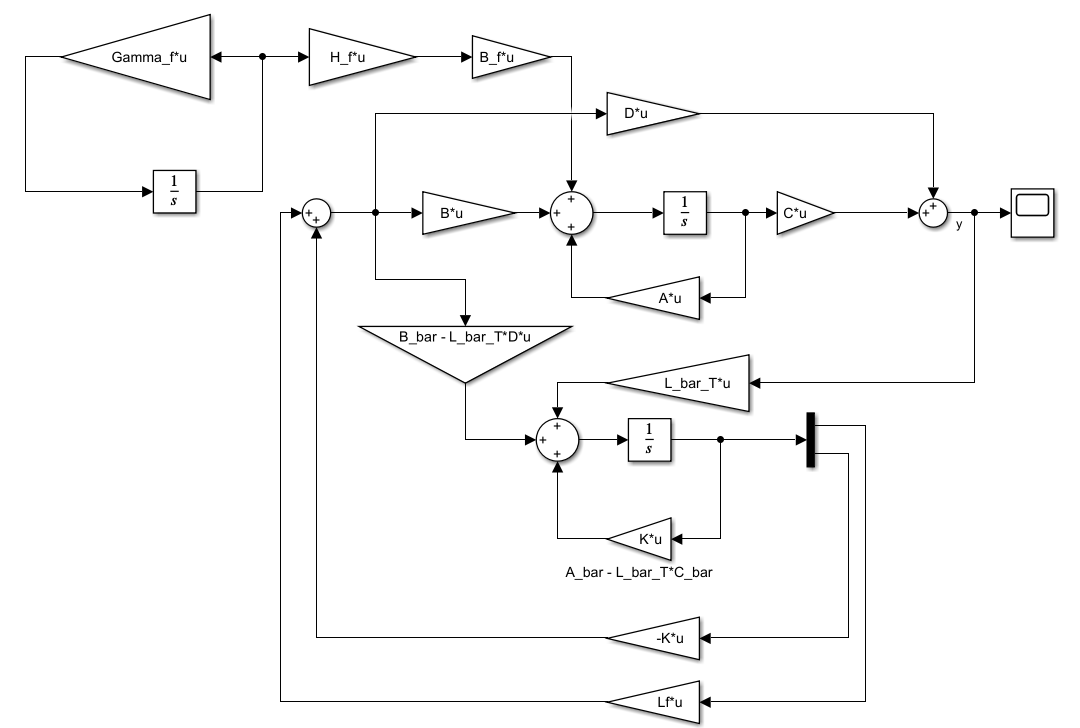

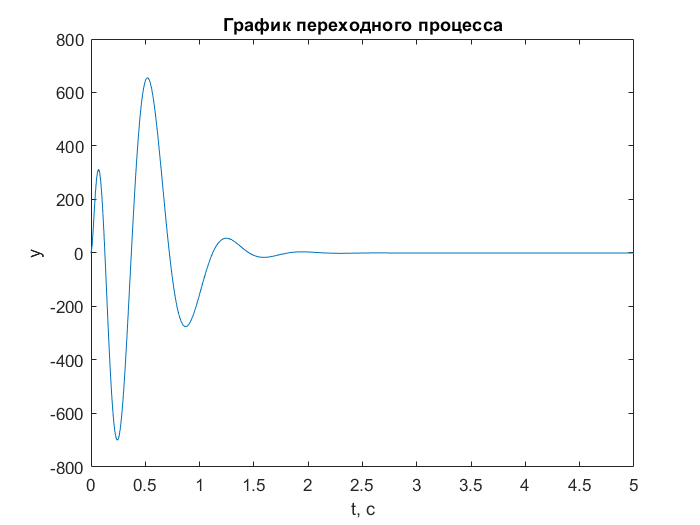

T = 5;
simu = sim("Task11_2_2");
plot(simu.y_real.time, simu.y_real.signals.values)
title('График переходного процесса')
xlabel('t, c')
ylabel('y')

### **3. Задача компенсации возмущений по выходу (стабилизация в условиях внешних возмущений).**

Целью управления является обеспечение выполнения следующего целевого равенства: $\lim_{t\to \infty } \left|\left|y\left(t\right)\right|\right|=0$

#### 3.1. Проверка объекта управления на свойства полной управляемости и наблюдаемости.

switch rank(ctrb(A, B))
    case rank(A)
        disp('система полностью управляема')
    otherwise
        disp('система не управляема')
end

система полностью управляема


switch rank([C; C*A])
    case rank(A)
        disp('система полностью наблюдаема')
    otherwise
        disp('система не полностью наблюдаема')
end

система полностью наблюдаема


#### 3.2. Формирование модели возмущающего воздействия на основе метода последовательного дифференцирования в виде:


$${\left\{\begin{array}{c}
{\dot{\xi} }_f =Г_f \xi_f \\
f=H_f \xi_f 
\end{array}\$$


xi_f_1(t) = f(t)

$$xi\_f\_1(t) = 6\,\sin\left(t+2\right)$$

xi_f_2(t) = diff(xi_f_1(t))

$$xi\_f\_2(t) = 6\,\cos\left(t+2\right)$$

k_xi_f_dot_2(t) = diff(xi_f_2(t))/xi_f_1(t)

$$k\_xi\_f\_dot\_2(t) = -1$$

xi_f_dot_2(t) = k_xi_f_dot_2(t) * xi_f_1(t)

$$xi\_f\_dot\_2(t) = -6\,\sin\left(t+2\right)$$

xif_0 = double([xi_f_1(0); xi_f_2(0)])

xif_0 =     5.4558
   -2.4969


Gamma_f = [0 1
    -w_f^2 0];
H_f = [1 0];

#### 3.3. Конструирование эталонной модели по желаемым корням .Нахождение матрицы M и матрицы линейных стационарных обратных связей K из уравнений:


$${\left\{\begin{array}{c}
MГ-AM=BH\\
K=-H*M^{-1} 
\end{array}$$


Gamma = [lambda_1 0
    0 lambda_2];
H = [1 1];
M = sylv(-A, Gamma, B*H)

M =     0.0263    0.0818
   -0.1842   -0.3545


K = -H/M

K =    29.6667    9.6667


#### 3.4. Расчёт матриц $M_f$  и $L_f$ из совместного решения двух векторно-матричных уравнений Франкиса-Дэвисона:


$${\left\{\begin{array}{c}
BL_f =M_f Г_f -\left(A-BK\right)M_f \\
{\left(C-DK\right)}M_f +DL_f +H_f =0
\end{array}$$


Mf = sym('mf', [2 2]);
Lf = sym('lf', [1 2]);
eqn1 = B*Lf == Mf*Gamma_f - (A - B*K)*Mf;
eqn2 = (C-D*K)*Mf + D*Lf + H_f == 0;
s = solve([eqn1; eqn2],[Mf; Lf]);
Lf = double([s.lf1 s.lf2])

Lf =    -1.3494   -0.8598


Mf = double([s.mf1_1 s.mf1_2
    s.mf2_1 s.mf2_2])

Mf =    -0.1034   -0.0414
    0.1862    0.0345


#### 3.5 Построим схему моделирования системы компенсации и получим графики переходных процессов:

Схема моделирования:

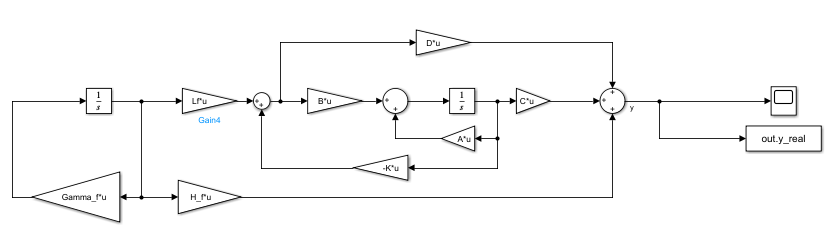

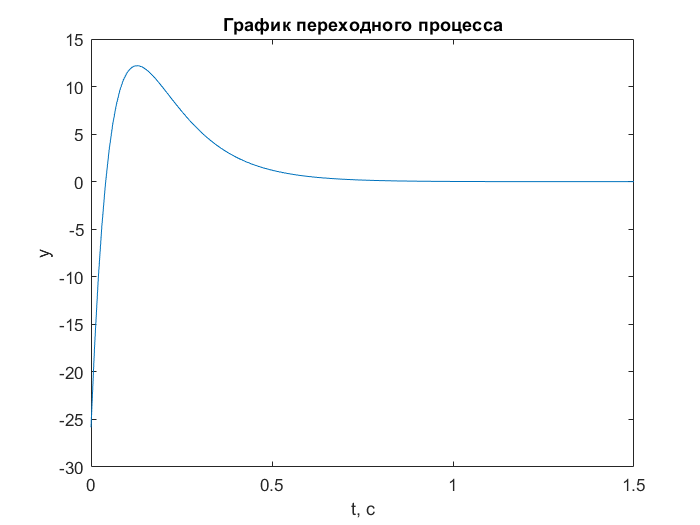

T = 1.5; %время моделирования
simu = sim("Task11_3_5");
plot(simu.y_real.time, simu.y_real.signals.values)
title('График переходного процесса')
xlabel('t, c')
ylabel('y')

#### 3.6-3.8. Для расширенного наблюдателя назначим матрицы эталонной модели $\bar{\Gamma_H }$ и  $\bar{H_H }$, матрицу $\bar{\Gamma_H }$определим на основе требуемых корней характеристического полинома, матрицу $\bar{H_H }$ находим из условия полной наблюдаемости эталонной модели: Определим матрицу $\bar{\Gamma_H }$, которая строится на основе требуемых показателей качества  и матрицу входа модели $\bar{H_H }$.  Поскольку желаемое перерегулирование больше 4,5% используем полином Баттерворта

syms s
w = 13.6;
a(s) = s^4+2.613*w*s^3++3.414*w^2*s^2+2.613*w^3*s + w^4;
a_s = sym2poly(a(s));
r = roots(a_s);
G_bar_H = [real(r(1)) imag(r(1)) 0 0
imag(r(2)) real(r(2)) 0 0
0 0 real(r(3)) imag(r(3))
0 0 imag(r(4)) real(r(4))] 

G_bar_H =    -5.2038   12.5651         0         0
  -12.5651   -5.2038         0         0
         0         0  -12.5646    5.2048
         0         0   -5.2048  -12.5646


H_bar_H = [1 0 1 0];
A_bar = [Gamma_f [0 0; 0 0]; B_f*H_f A];
B_bar = [0; 0; B];
C_bar = [0 0 C];
M_bar_H = sylv(-A_bar', G_bar_H, C_bar'*H_bar_H)

M_bar_H =    -0.0366    0.0828    0.0598    0.0445
    0.0067    0.0002   -0.0028   -0.0047
   -0.2031   -0.2380   -0.2580   -0.0723
   -0.0314    0.0615    0.0465    0.0365


L_bar = (-H_bar_H/M_bar_H)'

L_bar = 	1.0e+03 *

   -0.9177
    1.0151
    0.0081
    1.2652


#### 3.9 Вычислим корни характеристического полинома матрицы и сравним их с корнями требуемого характеристического полинома:

[eig(G_bar_H) roots(a_s)]

ans =   -5.2038 +12.5651i  -5.2038 +12.5651i
  -5.2038 -12.5651i  -5.2038 -12.5651i
 -12.5646 + 5.2048i -12.5646 + 5.2048i
 -12.5646 - 5.2048i -12.5646 - 5.2048i


#### 3.10 Произведем моделирование

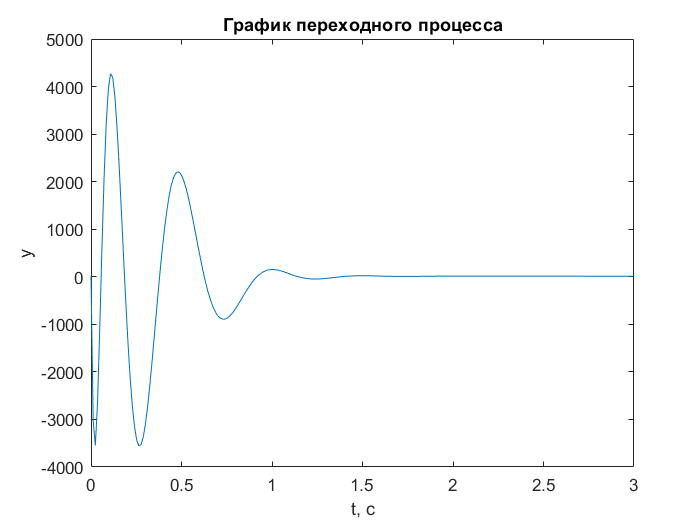

T = 3; %время моделирования
simu = sim("Task11_3_10");
plot(simu.y_real.time, simu.y_real.signals.values)
title('График переходного процесса')
xlabel('t, c')
ylabel('y')